# Problem 3-1

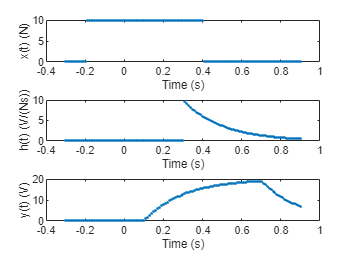

%3-1e
t_start = -0.3;
t_end = 0.9;
delta = 0.01;
t = t_start:delta:t_end;

x_start = -0.2;
x_end = 0.4;

x = [zeros(1, length(t_start:delta:x_start)),...
    repmat(10, [1,length(x_start+delta:delta:x_end)]),...
    zeros(1, length(x_end+delta:delta:t_end))];

h_start = 0.3;
t_h = h_start+delta:delta:t_end;
h = [zeros(1, length(t_start:delta:h_start)),...
    10*exp(-5.*(t_h-0.3))];

y_t1 = 0.1; % First transition point of y
y_t2 = 0.7; % Second transition point of y
t_y1 = t_start:delta:y_t1;
t_y2 = y_t1+delta:delta:y_t2;
t_y3 = y_t2+delta:delta:t_end;

y_1 = zeros(1,length(t_y1));
y_2 = 20 - 20*exp(-5.*(t_y2-0.1));
y_3 = 20*exp(-5.*(t_y3-0.7)) - 20*exp(-5.*(t_y3-0.1));
y = [y_1 y_2 y_3];

figure;
subplot(3,1,1)
plot(t,x,'.');
xlabel('Time (s)')
ylabel('x(t) (N)')

subplot(3,1,2)
plot(t,h,'.');
xlabel('Time (s)')
ylabel('h(t) (V/(Ns))')

subplot(3,1,3)
plot(t,y,'.');
xlabel('Time (s)')
ylabel('y(t) (V)')